# HW 3

clear; clc; clf;
% Q1-Q3
ao = 0.1

ao = 0.1000

bo = ao

bo = 0.1000

d = 6;
num = [bo];
den = [1 ao];
eh = tf(num,den,'InputDelay',d)

eh =
 
                0.1
  exp(-6*s) * -------
              s + 0.1
 
Continuous-time transfer function.
Model Properties


beh = tf(num,den)

beh =
 
    0.1
  -------
  s + 0.1
 
Continuous-time transfer function.
Model Properties


[NUM DEN] = pade(6,2)

NUM =     1.0000   -1.0000    0.3333


DEN =     1.0000    1.0000    0.3333



sure = tf(NUM,DEN)

sure =
 
  s^2 - s + 0.3333
  ----------------
  s^2 + s + 0.3333
 
Continuous-time transfer function.
Model Properties


ehbeh = sure*beh

ehbeh =
 
      0.1 s^2 - 0.1 s + 0.03333
  ----------------------------------
  s^3 + 1.1 s^2 + 0.4333 s + 0.03333
 
Continuous-time transfer function.
Model Properties


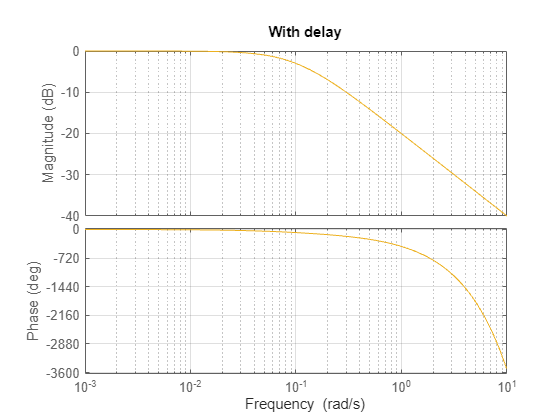


figure(1);
hold on;
bode(eh)
grid on;
title('With delay')
hold off;

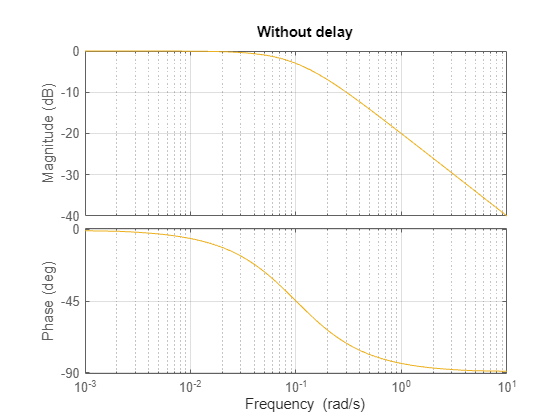


figure(2);
hold on;
bode(beh)
grid on;
title('Without delay')
hold off;

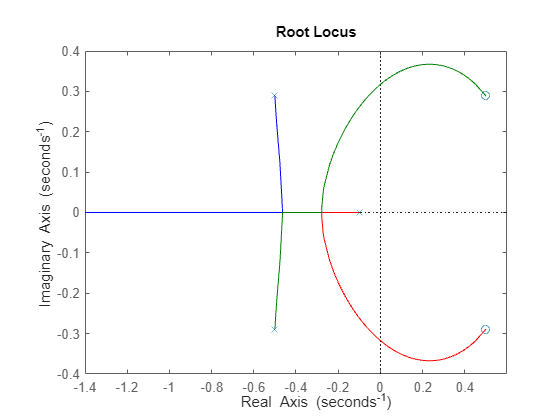




figure(3);
rlocus(ehbeh)

%grid on;


## Q4

clear; clc;

ao = 0.1

ao = 0.1000

bo = ao

bo = 0.1000

d = 6;
Ku = 3.26;
wu = 0.316;
Tu = 1/0.3;
a = 0.6;
b = 0.5;
c = 0.125;
Kp = a*Ku

Kp = 1.9560

Ti = b*Tu

Ti = 1.6667

Td = c*Tu

Td = 0.4167


num = [bo];
den = [1 ao];
beh = tf(num,den)

beh =
 
    0.1
  -------
  s + 0.1
 
Continuous-time transfer function.
Model Properties


[NUM DEN] = pade(6,2)

NUM =     1.0000   -1.0000    0.3333


DEN =     1.0000    1.0000    0.3333



sure = tf(NUM,DEN)

sure =
 
  s^2 - s + 0.3333
  ----------------
  s^2 + s + 0.3333
 
Continuous-time transfer function.
Model Properties


ehbeh = sure*beh

ehbeh =
 
      0.1 s^2 - 0.1 s + 0.03333
  ----------------------------------
  s^3 + 1.1 s^2 + 0.4333 s + 0.03333
 
Continuous-time transfer function.
Model Properties



num = [Kp*Td Kp Kp/Ti]

num =     0.8150    1.9560    1.1736


den = [1 0]

den =      1     0


Ds = tf(num,den)

Ds =
 
  0.815 s^2 + 1.956 s + 1.174
  ---------------------------
               s
 
Continuous-time transfer function.
Model Properties


ew = Ds*ehbeh

ew =
 
  0.0815 s^4 + 0.1141 s^3 - 0.05107 s^2 - 0.05216 s + 0.03912
  -----------------------------------------------------------
            s^4 + 1.1 s^3 + 0.4333 s^2 + 0.03333 s
 
Continuous-time transfer function.
Model Properties



figure(4);
bode(Ds)

Error using DynamicSystem/bode
Plots must be of the same type and size to be superimposed.